#### TRANSMITTER

%% QPSK Modulation and Rayleigh + Poisson Noise Addition - TRANSMITTER
clc; clear; close all;

%% Step 1: Load the Original Audio File
[audioIn, fs] = audioread('input_voice.wav');  
audioIn = audioIn(:, 1);  % Single channel
audioIn = audioIn / max(abs(audioIn));  % Normalize to [-1, 1]

disp('Playing Original Audio...');

Playing Original Audio...


sound(audioIn, fs);
pause(length(audioIn)/fs + 1);

%% Step 2: Convert Audio to Binary
scaledSignal = uint8((audioIn + 1) * 127);  
bits = reshape(de2bi(scaledSignal, 8, 'left-msb')', [], 1);  

%% Step 3: QPSK Modulation
M = 4;  
padLength = mod(-length(bits), log2(M));  
if padLength > 0, bits = [bits; zeros(padLength, 1)]; end

symbols = bi2de(reshape(bits, log2(M), [])', 'left-msb');  
modulatedSignal = pskmod(symbols, M, pi/4);  
modulatedSignal = modulatedSignal / max(abs(modulatedSignal));

%% Step 4: Simulate Wireless Channel
d = 100;  % Distance (m)
Pt = 1;  % Transmit Power
pathLoss = Pt / (d^2);  % Free-space path loss
shadowing = randn(size(modulatedSignal)) * 0.01;

% Rayleigh Noise
rayleighNoise = raylrnd(0.4, size(modulatedSignal));

% Poisson Noise
poissonNoise = poissrnd(0.01, size(modulatedSignal));

% Combine all effects
complexNoise = (rayleighNoise + poissonNoise) .* exp(1j * 2 * pi * rand(size(modulatedSignal)));
noisySignal = modulatedSignal * pathLoss + shadowing + complexNoise;

% Add AWGN (Thermal Noise)
desiredSNR_dB = 10;  
noisySignal = awgn(noisySignal, desiredSNR_dB, 'measured');

%% Step 5: Save Transmitted Signal
save('transmitted_signal.mat', 'noisySignal', 'fs', 'bits', 'audioIn', 'desiredSNR_dB', 'd');
disp('Transmission Complete: Signal Saved.');

Transmission Complete: Signal Saved.


#### RECEIVER

%% QPSK Demodulation and Noise Removal - RECEIVER
clc; clear; close all;

%% Step 1: Load Transmitted Signal
load('transmitted_signal.mat');
receivedSignal = noisySignal;

%% Step 2: Receiver Sensitivity Adjustment
receivedPower = mean(abs(receivedSignal).^2);
if receivedPower < 0.01
    disp('Low signal power detected. Increasing sensitivity...');
    receivedSignal = receivedSignal * 10;
end

%% Step 3: QPSK Demodulation
M = 4;
receivedSymbols = pskdemod(receivedSignal, M, pi/4);
receivedBits = reshape(de2bi(receivedSymbols, log2(M), 'left-msb')', [], 1);

%% Step 4: Reconstruct Audio
receivedBits = receivedBits(1:length(bits));  
receivedBytes = reshape(receivedBits, 8, [])';
receivedInts = bi2de(receivedBytes, 'left-msb');
audioReconstructed = (double(receivedInts) / 127) - 1;
audioReconstructed = audioReconstructed / max(abs(audioReconstructed));

%% Step 5: Apply Low-Pass Filter
[b, a] = butter(6, 7000 / (fs / 2), 'low');  
audioFiltered = filter(b, a, audioReconstructed);

%% Step 6: BER Calculation
bitErrors = sum(bits ~= receivedBits);
BER = bitErrors / length(bits);
fprintf('Bit Error Rate (BER): %.6f\n', BER);

Bit Error Rate (BER): 0.500392



%% Step 7: Play and Save Audio
disp('Playing Denoised Audio...');

Playing Denoised Audio...


sound(audioFiltered, fs);
pause(length(audioFiltered)/fs + 1);

audiowrite('denoised_audio.wav', audioFiltered, fs);

disp('Audio saved.');

Audio saved.


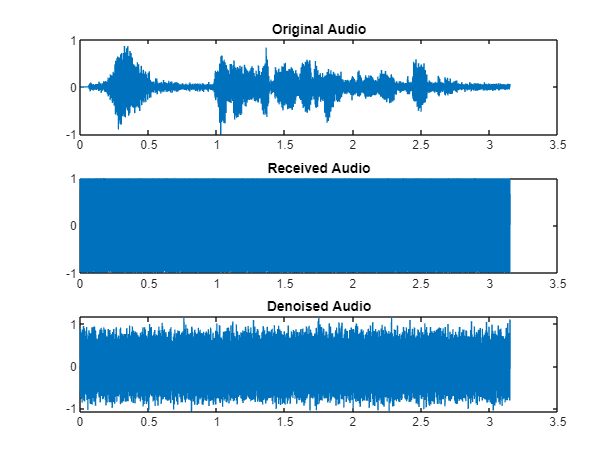


%% Plot Signals
t = (0:length(audioIn)-1) / fs;
figure;
subplot(3,1,1); plot(t, audioIn); title('Original Audio');
subplot(3,1,2); plot(t, audioReconstructed(1:length(t))); title('Received Audio');
subplot(3,1,3); plot(t, audioFiltered(1:length(t))); title('Denoised Audio');